Total_infections = 8.6547e+04

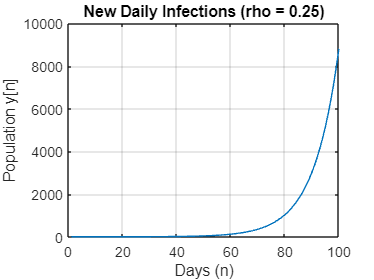

Total_infections = 137.5073

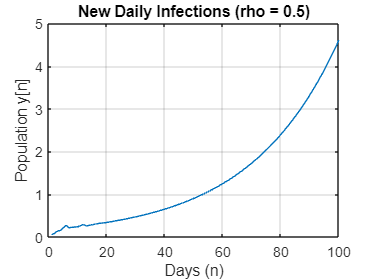

Total_infections = 1.5310

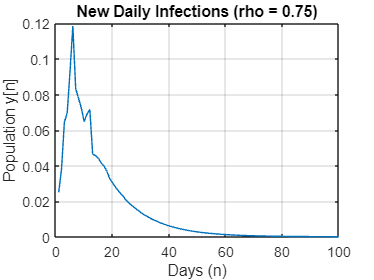

% Problem 3
rho = [0.25 0.50 0.75];
for i = rho
    H_new =1/( 1 + (1-i)*(- 0.1*z^-1 - 0.15*z^-2 - 0.25*z^-3 - 0.26*z^-4 - 0.34*z^-5 - 0.42*z^-6 - 0.25*z^-7 - 0.2*z^-8 - 0.15*z^-9 - 0.1*z^-10 - 0.1*z^-11 - 0.1*z^-12));
    ySol2 = iztrans(H_new,z,n); % Time domain equation
    ySol2 = simplify(ySol2); 
    nValues2 = 1:100;
    ySolValues2 = subs(ySol2,n,nValues2);
    ySolValues2 = double(ySolValues2);
    ySolValues2 = real(ySolValues2);
    Integrator2 = filter(1,[1 -1],ySolValues2);
    Total_infections = Integrator2(end) % Total infections in 100 days
    figure;
    plot(nValues2,ySolValues2)
    title("New Daily Infections (rho = "+ i+")")
    xlabel("Days (n)")
    ylabel("Population y[n]")
    grid on
end